Tạo model

model = createpde("thermal","transient");

Import a geometry into the container.

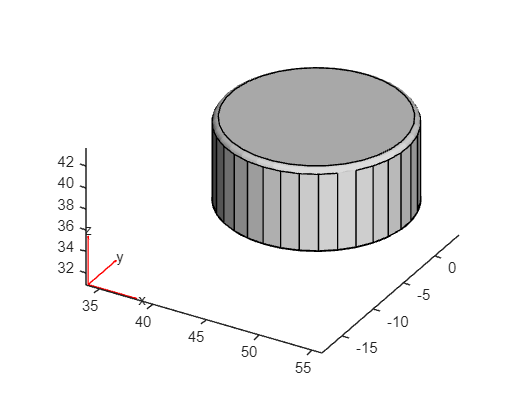

importGeometry(model,"cau_truc\break_disk\Brake_Piston_1.stl");
pdegplot(model);

Edge Labels

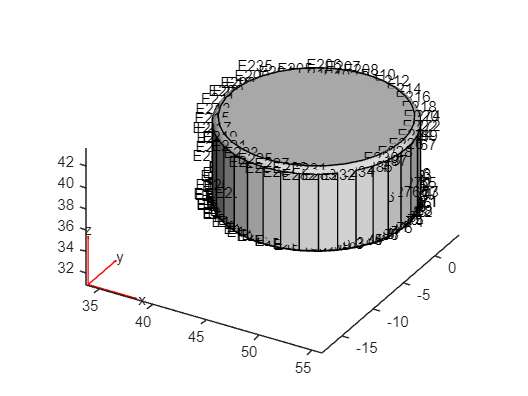

pdegplot(model, "EdgeLabels","on")

Cấu trúc vật thể

gm = generateMesh(model)

gm =   FEMesh with properties:

             Nodes: [3×23140 double]
          Elements: [10×11992 double]
    MaxElementSize: 0.9096
    MinElementSize: 0.3790
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


Import Mesh

mesh = generateMesh(model)

mesh =   FEMesh with properties:

             Nodes: [3×23140 double]
          Elements: [10×11992 double]
    MaxElementSize: 0.9096
    MinElementSize: 0.3790
     MeshGradation: 1.5000
    GeometricOrder: 'quadratic'


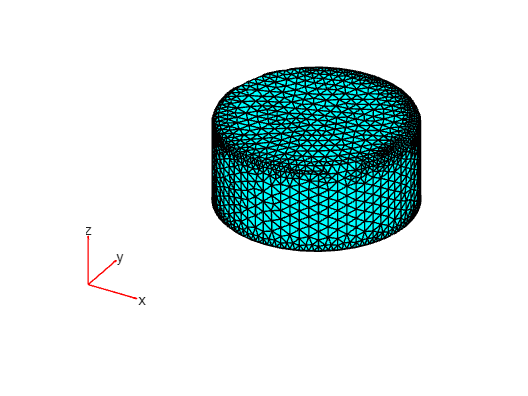

figure
pdemesh(model)

Specify the thermal properties of the material.

thermalProperties(model,"ThermalConductivity",100, ...
                        "MassDensity",8000, ...
                        "SpecificHeat",500);

Specify the boundary conditions. All the faces are exposed to air, so there will be free convection.

thermalBC(model,"Face",1:model.Geometry.NumFaces, ...
                "ConvectionCoefficient",10, ...
                "AmbientTemperature",30);

Model the moving heat source by using a function handle that defines the thermal load as a function of space and time. For the definition of the `movingHeatSource` function, see the Heat Source Functions section at the bottom of this page.

thermalBC(model,"Face",11,"HeatFlux",@movingHeatSource); 

Error using pde.ThermalBC (line 87)
The value of 'HeatFlux' is invalid. Function movingHeatSource does not exist.

Error in pde.ThermalModel/thermalBC (line 154)
    bc = pde.ThermalBC(self.BoundaryConditions,argsToPass{:});

thermalBC(model,"Face",4,"HeatFlux",@movingHeatSource); 

Specify the initial temperature.

thermalIC(model,30);

Solve the model for the time steps from 0 to 25 ms.

tlist = linspace(0,0.025,100); % Half revolution
R1 = solve(model,tlist);

Plot the temperature distribution at 25 ms.

figure("units","normalized","outerposition",[0 0 1 1])
pdeplot3D(model,"ColorMapData",R1.Temperature(:,end))
